# BCN Analisis electrolinera

clc
clearvars
close all

Script for importing data from the following text file:

Auto-generated by MATLAB on 22-Mar-2022 10:33:45

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 18);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ";";

% Specify column names and types
opts.VariableNames = ["ID", "CHARGINGPOINT", "CONNECTOR", "STARTTIME", "STOPTIME", "DURATIONmin", "CONSUMPTIONkWh", "VEHICLE", "MODEL", "Charger", "AvPower", "Day", "ora", "Mins", "mese", "BatteriaEkWh", "FractSOC", "Pmax"];
opts.VariableTypes = ["double", "categorical", "categorical", "datetime", "datetime", "double", "double", "categorical", "categorical", "categorical", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["CHARGINGPOINT", "CONNECTOR", "VEHICLE", "MODEL", "Charger"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "STARTTIME", "InputFormat", "dd/MM/yyyy");
opts = setvaropts(opts, "STOPTIME", "InputFormat", "dd/MM/yyyy");

% Import the data
data = readtable("C:\Users\jyeregui\Dropbox (MGEP)\Josu\2. BrainEN\BrainEN-Electrolinera\Load Profile Generator\BCN\Data\Charge2019_EV_AMB.csv", opts)

data = 36413×18 table
    ID                                    CHARGINGPOINT                                         CONNECTOR         STARTTIME      STOPTIME     DURATIONmin    CONSUMPTIONkWh      VEHICLE          MODEL         Charger    AvPower    Day    ora    Mins    mese    BatteriaEkWh    FractSOC    Pmax
    __    ______________________________________________________________________________    __________________    __________    __________    ___________    ______________    ___________    ______________    _______

clear opts

### Procesar tabla

% 
[~, data.StartWeek] = weekday(data.STARTTIME);
data.StartWeek = cellstr(data.StartWeek);
data = convertvars(data, {'StartWeek', 'Charger', 'CHARGINGPOINT'}, 'categorical');

data.Arrival = data.ora * 60 + data.Mins;
data.Departure = data.Arrival + data.DURATIONmin;

### Histogramas electrolineras 1 Día

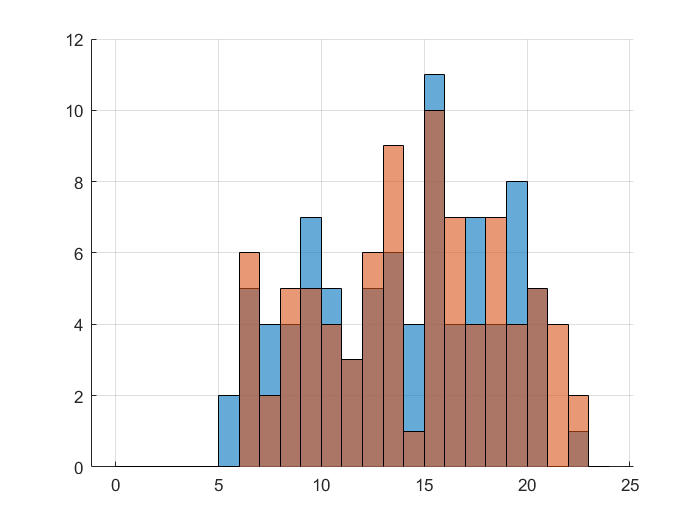

day = 74;
pos_days = unique(data.STARTTIME);
data_day = data(data.STARTTIME == pos_days(day), ["Arrival", "Departure"]);

figure
hold on
grid on
histogram(data_day.Arrival/60, 0:24)
histogram(data_day.Departure/60, 0:24)

### Extraccioón de distribuciones semanales

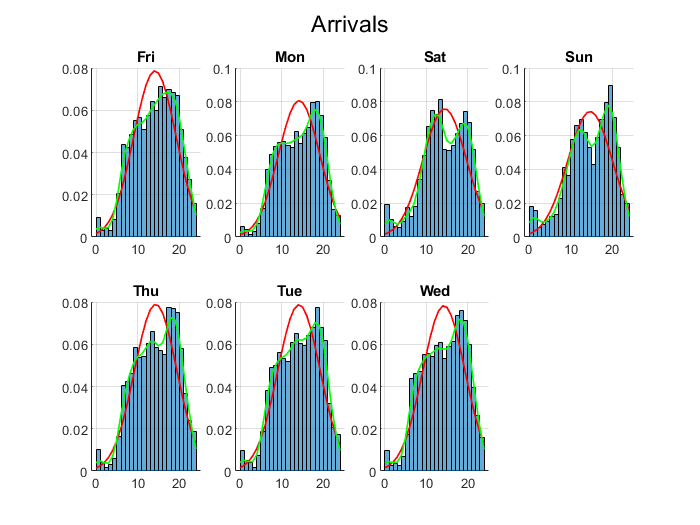

poss_day = categories(data.StartWeek);
figure
sgtitle('Arrivals')
hold on
for k = 1:length(categories(data.StartWeek))
    dat_weekday = data(data.StartWeek == poss_day(k), :);

    mu = mean(dat_weekday.Arrival/60);
    sigma = std(dat_weekday.Arrival/60);
    pd_Ker = fitdist(dat_weekday.Arrival/60, "Kernel");
    
    subplot(2, ceil(length(categories(data.StartWeek))/2), k)
    hold on
    grid on
    title(poss_day(k))
    h = histogram(dat_weekday.Arrival/60, 0:24, 'Normalization', "pdf");
    plot(0:24, normpdf(0:24, mu, sigma), '-r', 'LineWidth', 1)
    plot(0:24, pdf(pd_Ker, 0:24), '-g', 'LineWidth', 1)
end

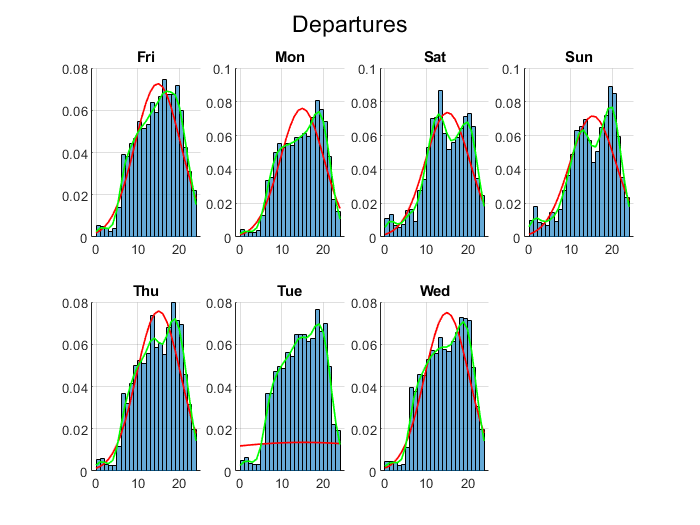

figure
sgtitle('Departures')
hold on
for k = 1:length(categories(data.StartWeek))
    dat_weekday = data(data.StartWeek == poss_day(k), :);

    mu = mean(dat_weekday.Departure/60);
    sigma = std(dat_weekday.Departure/60);
    pd_Ker = fitdist(dat_weekday.Departure/60, "Kernel");
    
    subplot(2, ceil(length(categories(data.StartWeek))/2), k)
    hold on
    grid on
    title(poss_day(k))
    h = histogram(dat_weekday.Departure/60, 0:24, 'Normalization', "pdf");
    plot(0:24, normpdf(0:24, mu, sigma), '-r', 'LineWidth', 1)
    plot(0:24, pdf(pd_Ker, 0:24), '-g', 'LineWidth', 1)
end

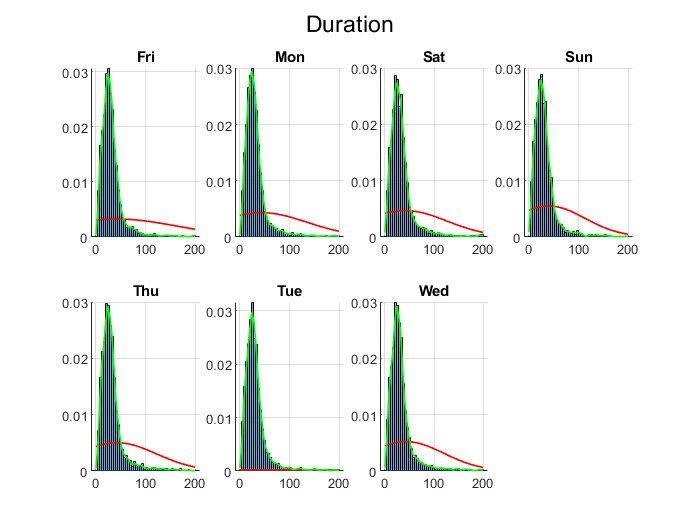

figure
sgtitle('Duration')
hold on
for k = 1:length(categories(data.StartWeek))
    dat_weekday = data(data.StartWeek == poss_day(k), :);

    mu = mean(dat_weekday.DURATIONmin);
    sigma = std(dat_weekday.DURATIONmin);
    pd_Ker = fitdist(dat_weekday.DURATIONmin, "Kernel");
    
    subplot(2, ceil(length(categories(data.StartWeek))/2), k)
    hold on
    grid on
    title(poss_day(k))
    h = histogram(dat_weekday.DURATIONmin, 0:4:200, 'Normalization', "pdf");
    plot(0:4:200, normpdf(0:4:200, mu, sigma), '-r', 'LineWidth', 1)
    plot(0:4:200, pdf(pd_Ker, 0:4:200), '-g', 'LineWidth', 1)
end

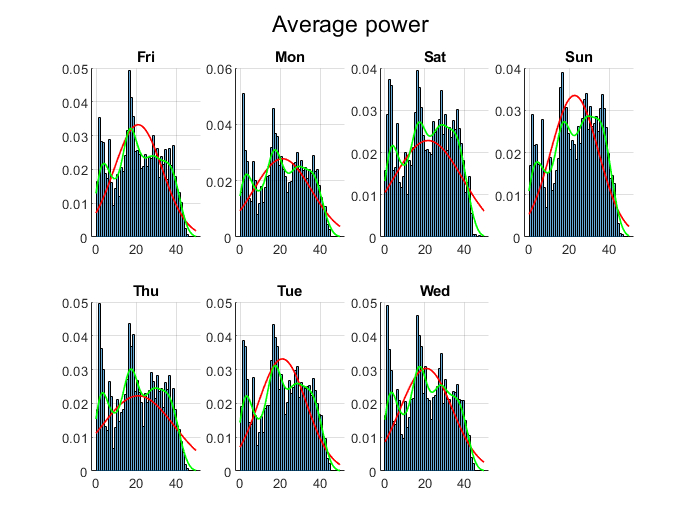

figure
sgtitle('Average power')
hold on
for k = 1:length(categories(data.StartWeek))
    dat_weekday = data(data.StartWeek == poss_day(k), :);

    mu = mean(dat_weekday.AvPower);
    sigma = std(dat_weekday.AvPower);
    pd_Ker = fitdist(dat_weekday.AvPower, "Kernel");
    
    subplot(2, ceil(length(categories(data.StartWeek))/2), k)
    hold on
    grid on
    title(poss_day(k))
    h = histogram(dat_weekday.AvPower, 0:50, 'Normalization', "pdf");
    plot(0:50, normpdf(0:50, mu, sigma), '-r', 'LineWidth', 1)
    plot(0:50, pdf(pd_Ker, 0:50), '-g', 'LineWidth', 1)
end

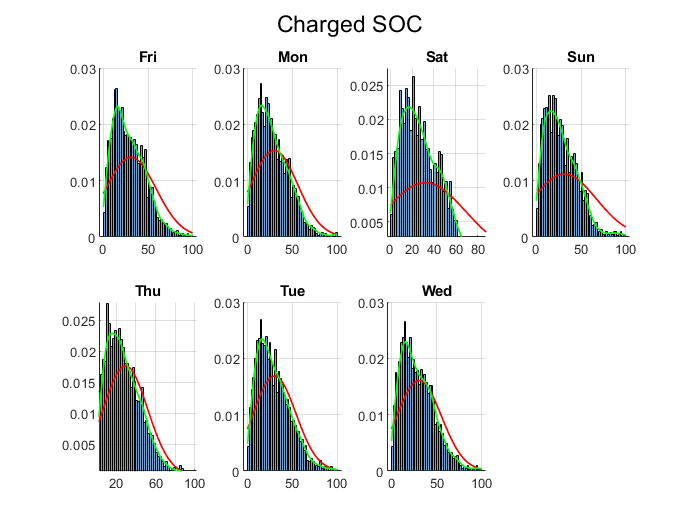

figure
sgtitle('Charged SOC')
hold on
for k = 1:length(categories(data.StartWeek))
    dat_weekday = data(data.StartWeek == poss_day(k), :);
    dat_weekday = dat_weekday(~isnan(dat_weekday.FractSOC), :);

    mu = mean(dat_weekday.FractSOC);
    sigma = std(dat_weekday.FractSOC);
    pd_Ker = fitdist(dat_weekday.FractSOC, "Kernel");
    
    subplot(2, ceil(length(categories(data.StartWeek))/2), k)
    hold on
    grid on
    title(poss_day(k))
    h = histogram(dat_weekday.FractSOC, 0:2:100, 'Normalization', "pdf");
    plot(0:2:100, normpdf(0:2:100, mu, sigma), '-r', 'LineWidth', 1)
    plot(0:2:100, pdf(pd_Ker, 0:2:100), '-g', 'LineWidth', 1)
end

### Extract Kernel distribution functions for weekday/weekends

dat_weekend = data(data.StartWeek == "Sat" | data.StartWeek == "Sun", :);
pdKer_Weekend_Arrival = fitdist(dat_weekend.Arrival/60, "Kernel");
pdKer_Weekend_Departures = fitdist(dat_weekend.Departure/60, "Kernel");

dat_weekday = data(data.StartWeek ~= "Sat" & data.StartWeek ~= "Sun", :);
pdKer_Weekday_Arrival = fitdist(dat_weekday.Arrival/60, "Kernel");
pdKer_Weekday_Departures = fitdist(dat_weekday.Departure/60, "Kernel");

save("PDF_Kernerls", "pdKer_Weekday_Arrival", "pdKer_Weekend_Arrival",...
    "pdKer_Weekday_Departures", "pdKer_Weekend_Departures")